## Test Env Module

env = Env();

[20-Dec-2021 17:09:19]: Creating Env object...
[20-Dec-2021 17:09:20]: Creating Planner object...
[20-Dec-2021 17:09:20]: Creating Reward object...
[20-Dec-2021 17:09:20]: Loding configuration info...


test function load scenario

[env, vehicleSet, vehiclesTrajectory] = env.load_scenario("Scenario/04.mat", 1);

[20-Dec-2021 17:09:20]: Loading Scenario Data from Scenario/04.mat...


test function load road

x = [-10, 0: 100: 500];
y = zeros(size(x));
waypoint = [x', y'];

env = env.load_road(waypoint, vehicleSet, vehiclesTrajectory);

[20-Dec-2021 17:09:25]: Loading road data...
[20-Dec-2021 17:09:25]: Creating Road object...
[20-Dec-2021 17:09:25]: Adding Vehicles object...


test function reset

% env = env.reset();

% env = env.reset('index', 9);

% env = env.reset('filename', 'Scenario/30.mat');

## Test Planner Module

% planner = Planner();
% 
% startState = [0, 10, 0];
% endState = [90, 20, 0];
% 
% resultS = planner.quintic_planning_s(startState, endState, 6, 0.04);
% 
% figure;
% hold on;
% plot(resultS.t, resultS.s);
% plot(resultS.t, resultS.s_dot);
% plot(resultS.t, resultS.s_ddot);
% hold off;
% 
% startStateD = [0, 0, 0];
% endStateD = [3.6, 0, 0];
% resultD = planner.quintic_planning_l(startStateD, endStateD, resultS);
% 
% figure;
% plot(resultD.t, resultD.l);
% hold on;
% plot(resultD.t, resultD.l_dot);
% plot(resultD.t, resultD.l_ddot);
% hold off;
% 
% startStateD = [1.8, 0, 0];
% endStateD = [5.4, 0, 0];
% resultD = planner.quartic_planning_l(startStateD, endStateD, resultS);
% 
% figure;
% plot(resultD.t, resultD.l);
% hold on;
% plot(resultD.t, resultD.l_dot);
% plot(resultD.t, resultD.l_ddot);
% hold off;
% 
% startState = [startState, startStateD];
% endState = [endState, endStateD];
% result1 = planner.get_trajectory(startState, endState, 6, 0.04, 1);
% planner.check_trajectory(result1.trajectory)
% result2 = planner.get_trajectory(startState, endState, 6, 0.04, 0);
% planner.check_trajectory(result2.trajectory)

test planner in env module

% startState = env.RoadInstance.get_vehicle_frenetstate(1)
% 
% endState = [env.Conf.MaxS, env.Conf.MaxSpeed, 0, 1.8, 0, 0]
% 
% T = 2 * (endState(1) - startState(1)) / (endState(2) + startState(2))
% 
% plannResult = env.PlannerInstance.get_trajectory(startState, endState, T, env.Conf.TimeResolution, 1);
% 
% env.PlannerInstance.check_trajectory(plannResult.trajectory);
% 
% globalTrajectory = env.RoadInstance.frenet_to_global_trajectory(plannResult.trajectory)

## Test Road Module

test function get current lane

% lane1 = road.get_current_lane([2.3, 1.8]);
% lane2 = road.get_current_lane([2.3, 5.4]);
% lane3 = road.get_current_lane([2.3, 9.0]);

test the transformer

% frenetTestAns = global2frenet(road.refPath, [10, 0, 0, 0, 0, 0]);
% GlobalTestAns = frenet2global(road.refPath, [20, 0, 0, 5.4, 0, 0]);

test function get surrounding car

% frontCar = {};
% behindCar = {};
% for i = 1:9
%     [frontCar{i}, behindCar{i}] = road.get_surrounding_car(i);
% end

test function car to state

% state = {};
% for i = 1: 9
%     state{i} = road.car_to_state(i, frontCar{1, i}, behindCar{1, i});
% end

test function check collision

% flag = {};
% for i = 1: 9
%     flag{i} = road.check_collision(i);      % need to get global state of car firstly
% end

test road in env module

% [env.RoadInstance, moveResult] = env.RoadInstance.move_along_trajectory(globalTrajectory, 0);

## Test Vehicle Module

test construction function

% vehicle1 = Vehicle([2.3, 1.8]); % default construction function
% vehicle2 = Vehicle([2.3, 5.4], 'longvelocity', 3.0, 'latvelocity', 0, 'length', 4.0, 'width', 2.0, 'yaw', pi/6); % change default parameters

## Test Vistor Module

% plot(road.Vistor.Scenario);

test vistor in env module

% env.RoadInstance = env.RoadInstance.add_vistor(waypoint);
% 
% % 这玩意儿在这个实施编辑器显示不出来
% env.RoadInstance.move_along_trajectory_vistor(globalTrajectory, 0);

## Test Reward Module

% reward = Reward();

test cal all reward function

% reward = reward.cal_all_reward(result1.trajectory);

## Test Logger Module

## Test the Reinforcement Learning

Initiate the info of observation

obsInfo = rlNumericSpec([14, 1]);
obsInfo.Name = "State";
obsInfo.LowerLimit = [-1, -1,...
                      -1, -inf,...
                      -1, -inf,...
                      -1, -inf,...
                      -201, -inf,...
                      -201, -inf,...
                      -201, -inf];
obsInfo.UpperLimit = [500, inf,...
                      201, inf,...
                      201, inf,...
                      201, inf,...
                      1, inf,...
                      1, inf,...
                      1, inf];

Initiate the info of action

actInfo = rlNumericSpec([7, 1]);
actInfo.Name = "Action";
actInfo.LowerLimit = [0, -50, -50, -10, -10, -10, 0];
actInfo.UpperLimit = [500, 50, 50, 10, 10, 10, 10];

Initiate the rl env object

resetHandle = @() MyResetFunc(env);
stepHandle = @(Action, LoggedSignals) MyStepFunc(Action, LoggedSignals);

Initiate the rl func

rlEnv = rlFunctionEnv(obsInfo, actInfo, stepHandle, resetHandle);

[20-Dec-2021 20:27:44]: Env object reseting...
[20-Dec-2021 20:27:44]: Adding Vehicles object...
[20-Dec-2021 20:27:44]: Env object reseting...
[20-Dec-2021 20:27:44]: Adding Vehicles object...


Initiate the agent object

%   initiate the critic Net
obsPath = [
    featureInputLayer(obsInfo.Dimension(1), 'Normalization', 'none', 'Name', 'State'),...          
    fullyConnectedLayer(30, 'Name', 'ObsPathFC1'),...
    reluLayer('Name', 'ObsRelu1'),...
    fullyConnectedLayer(10, 'Name', 'ObsPathFC2'),...
    reluLayer('Name', 'ObsOut')];        

%   initiate the critic Net
actorPath = [
    featureInputLayer(actInfo.Dimension(1), 'Normalization', 'none', 'Name', 'Action'),...          
    fullyConnectedLayer(30, 'Name', 'ActorPathFC1'),...
    reluLayer('Name', 'ActorRelu1'),...
    fullyConnectedLayer(10, 'Name', 'ActorPathFC2'),...
    reluLayer('Name', 'ActOut')];  

comPath = [additionLayer(2,'Name', 'add'),...
    fullyConnectedLayer(1, 'Name', 'ComPathFC1'),...
    reluLayer('Name', 'QValue')];

comPath =   具有以下层的 1×3 Layer 数组:

     1   'add'          加法     加法: 将 2 个输入按元素相加
     2   'ComPathFC1'   全连接   1 全连接层
     3   'QValue'       ReLU    ReLU

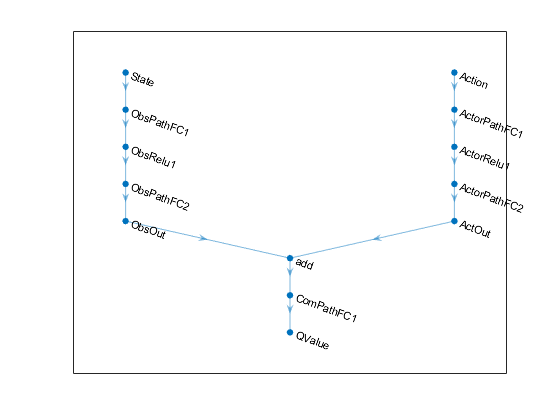


net = addLayers(layerGraph(obsPath), actorPath);
net = addLayers(net, comPath);

net = connectLayers(net,'ObsOut', 'add/in1');
net = connectLayers(net,'ActOut', 'add/in2');

figure;

lgraph = layerGraph(net);
plot(lgraph);
title('QNetwork');

% obsInfoTemp = rlEnv.getObservationInfo();
% actInfoTemp = rlEnv.getActionInfo();
% 
% %   https://ww2.mathworks.cn/help/reinforcement-learning/ug/create-policy-and-value-function-representations.html
criticOpts = rlRepresentationOptions('LearnRate', 0.001, 'GradientThreshold', 1, 'UseDevice', 'gpu');
critic = rlQValueRepresentation(net, obsInfo, actInfo,...
    'Observation', {'State'}, 'Action', {'Action'}, criticOpts);


错误使用 rlValueRepresentation (第 43 行)
输入参数太多。

agent = rlDQNAgent(critic, agentOpts);

plot the agent structure

% plot(agent);